# BPSK Modulator Simulation

## Theoretical background

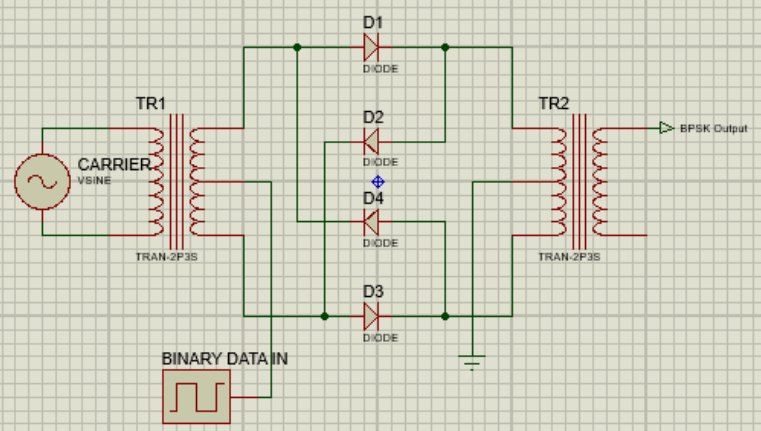

- Above is a BPSK modulator which uses a balanced modulator. 

- The carrier wave is a high frequency sinusoidal wave and the binary data input waveform is a square wave of amplitudes +1 V and -1 V corresponding to binary values 1 and 0 respectively. 

- The diodes control the "orientation" of the sine wave that is passed through the transformer TR2. When the binary data input is +1 V, the BPSK output is equal to the carrier wave, or has no phase difference. When the binary data input is - 1 V, the BPSK output and the carrier wave will have a 180-degree phase difference, hence the modulation scheme "BPSK".

- The simulation will assume the transformers TR1 and TR2 specifications to be 1:1 and that there is no voltage drop across the diodes. Hence only the phase of the waveforms shall change.

- Below are the expected waveforms (from [What is Phase Shift Keying (PSK)? BPSK modulation, BPSK demodulation, advantages, disadvantages and applications of PSK - Electronics Coach](https://electronicscoach.com/phase-shift-keying.html)):

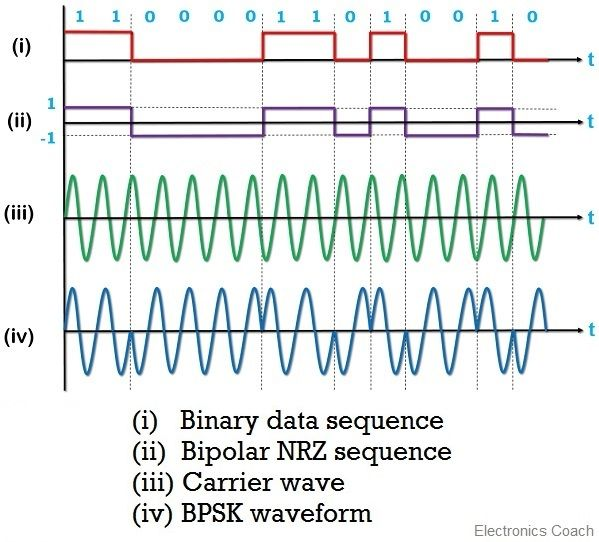

## Simulation of BPSK modulator (No graphing, Initial)

- The scheme for assigning values according to the binary input was completely the opposite hence the 100% BER compared to the pskdemod output.

### Model the binary data

nbits = 1000;
bits = randi([0 1], 1, nbits)

bits =      0     1     1     0     1     0     0     1     0     0     0     1     0     1     1     1     1     1     1     1     0     1     0     0     0     0     1     0     0     0     0     1     0     1     0     1     0     0     1     0     0     1     0     1     0     1     0     0     1     1


### Generate the complex envelope

cmplx_env = zeros(size(bits));
for i = 1 : length(bits)
    if bits(i) == 1
        cmplx_env(i) = 1;
    elseif bits(i) == 0
        cmplx_env(i) = -1;
    end
end
cmplx_env = complex(cmplx_env)

cmplx_env =   -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


### Add white Gaussian noise to the complex envelope

SNR = 10;
noise_cmplx_env = awgn(cmplx_env, SNR)

noise_cmplx_env =   -0.5218 - 0.0795i   1.0987 + 0.5865i   0.9635 - 0.0866i  -1.0015 + 0.2162i   0.9903 - 0.0560i  -1.1457 + 0.0485i  -0.6335 - 0.3762i   0.9336 + 0.3141i  -0.7321 - 0.2489i  -0.7528 - 0.4136i  -0.8564 - 0.0483i   0.8441 - 0.0617i  -1.2865 - 0.2528i   0.7808 + 0.2910i   1.1093 - 0.2332i   0.8817 - 0.2682i   0.9918 - 0.2199i   1.1776 + 0.1868i   0.9859 - 0.1104i   1.0252 + 0.0784i  -0.9004 - 0.1457i   0.6322 + 0.0414i  -1.1997 - 0.3510i  -0.7200 - 0.0950i  -1.2108 - 0.0734i  -1.0666 - 0.2647i   0.7419 - 0.2335i  -1.1768 + 0.1266i  -0.8956 - 0.0656i  -1.2522 - 0.2513i  -1.1418 - 0.3359i   1.0353 + 0.3067i  -1.0608 - 0.0454i   1.1293 - 0.2287i  -0.9552 + 0.3258i   0.9003 + 0.2032i  -0.9850 + 0.3163i  -0.8305 + 0.1271i   1.0731 - 0.0334i  -0.6010 + 0.1420i  -0.9231 + 0.1519i   0.7261 - 0.4102i  -0.7534 + 0.2062i   0.8693 - 0.0817i  -0.9485 + 0.1100i   1.7205 - 0.2072i  -0.5530 + 0.0581i  -1.3615 - 0.1628i   1.2793 + 0.1466i   0.9501 + 0.4354i


### Plot the BPSK constellation diagram

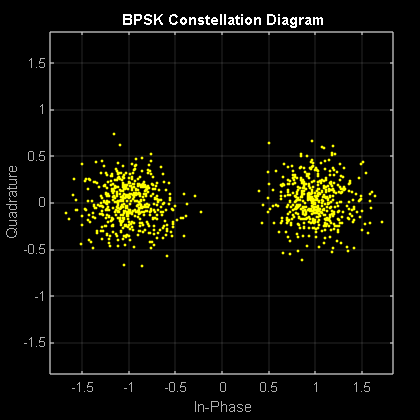

figure(2)
scatterplot(noise_cmplx_env)
title("BPSK Constellation Diagram")
grid on

### Recover the bits from the noisy BPSK-modulated signal

recovered_bits = zeros(size(bits));
for i = 1 : length(noise_cmplx_env)
    if real(noise_cmplx_env(i)) >= 0
        recovered_bits(i) = 1;
    end
end

### Compute for the bit error rate

[number, ratio] = biterr(bits, recovered_bits)

number = 0

ratio = 0

## Simulation of BPSK modulator (No graphing, Final)

- Scheme for generating the complex envelope is updated to match that of the built in function.

### Model the binary data

nbits = 1000;
bits = randi([0 1], 1, nbits)

bits =      1     1     1     0     0     0     1     0     0     1     1     1     0     0     0     0     0     1     0     0     1     1     0     0     1     0     0     1     1     0     0     0     1     0     1     0     1     1     0     1     1     1     0     1     0     1     1     0     1     0


### Generate the complex envelope

cmplx_env = zeros(size(bits));
for i = 1 : length(bits)
    switch(bits(i))
        case 1
            cmplx_env(i) = -1;
        case 0
            cmplx_env(i) = 1;
        otherwise
            error("Error in bit generation")
    end
end
cmplx_env = complex(cmplx_env)

cmplx_env =   -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i


### Add white Gaussian noise to the complex envelope

SNR = 10;
noise_cmplx_env = awgn(cmplx_env, SNR)

noise_cmplx_env =   -0.9756 - 0.0344i  -1.1658 - 0.0100i  -0.8788 + 0.2294i   0.7732 - 0.3806i   1.2905 + 0.0166i   1.1261 + 0.1438i  -1.0027 - 0.1161i   1.0274 + 0.1036i   0.7001 + 0.0983i  -0.9805 + 0.0487i  -1.0200 - 0.1867i  -1.2310 - 0.0877i   1.4738 + 0.2190i   1.3229 - 0.0667i   0.9847 + 0.0343i   1.4100 + 0.1576i   0.9314 - 0.1304i  -0.9091 + 0.0485i   1.0338 - 0.5385i   0.9491 + 0.1687i  -1.1181 - 0.0447i  -0.8321 + 0.0950i   1.2073 - 0.0654i   0.8983 - 0.0616i  -1.2528 - 0.0716i   0.7143 - 0.2236i   1.0104 - 0.0670i  -1.3188 + 0.2962i  -1.0841 + 0.0944i   0.8140 - 0.0716i   1.1015 - 0.2617i   1.5309 - 0.1598i  -0.8370 + 0.1307i   0.8418 + 0.2243i  -0.7684 + 0.0698i   1.1355 - 0.3237i  -0.7345 - 0.1689i  -0.7215 - 0.3001i   1.0198 - 0.1751i  -1.1061 + 0.2766i  -1.0658 + 0.1963i  -0.8788 - 0.3544i   0.5893 + 0.3739i  -1.1959 + 0.2642i   0.8082 - 0.0968i  -0.9438 - 0.2305i  -1.0833 + 0.0545i   0.8305 - 0.1443i  -1.1730 - 0.1308i   0.5841 - 0.1841i


### Plot the BPSK constellation diagram

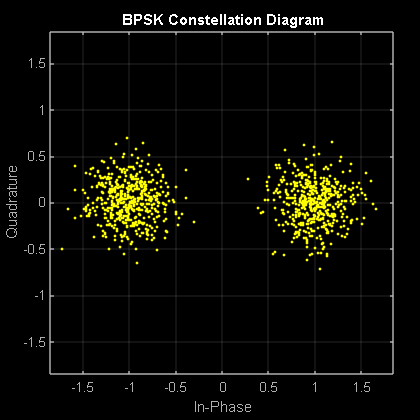

figure(2)
scatterplot(noise_cmplx_env)
title("BPSK Constellation Diagram")
grid on

### Recover the bits from the noisy BPSK-modulated signal

recovered_bits = zeros(size(bits));
for i = 1 : length(noise_cmplx_env)
    if real(noise_cmplx_env(i)) < 0
        recovered_bits(i) = 1;
    elseif real(noise_cmplx_env(i)) >= 0 
        % do nothing since array is already zeros
    else
        error("Error in complex envelope generation")
    end
end

### Compute for the bit error rate

[number, ratio] = biterr(bits, recovered_bits);
fprintf("System found " + num2str(number) + " number of bits in error. Resulting BER is " + num2str(ratio*100) + " percent.")

System found 0 number of bits in error. Resulting BER is 0 percent.

## Replication of BPSK using built-in MATLAB functions

### Generate the complex envelope using the pskmod() function

complex_envelope = pskmod(bits, 2)

complex_envelope =    1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i


### Add white Gaussian noise to the modulated waveform

%noise_complex_envelope = awgn(complex_envelope, SNR)

### Recover the bits 

recovered_bits = pskdemod(noise_cmplx_env, 2)

recovered_bits =      0     0     1     1     0     1     1     0     1     1     0     1     0     0     0     1     0     1     1     0     0     0     1     1     1     0     1     1     0     0     1     0     1     1     0     1     1     1     1     0     0     0     0     0     1     1     1     1     0     1


[number, ratio] = biterr(bits, recovered_bits)

number = 0

ratio = 0

## Simulation of BPSK modulator

### Model the carrier

fc = 1e6;
Ac = 5;

### Generate the time vector

t = linspace(0, 1/fc, fc);

### Model the binary data

nbits = 8;
bits = randi([0 1], 1, nbits)

bits =      0     0     0     1     0     1     1     1


### Generate the binary waveforms

bin = zeros(size(bits));
binwave = [];
NRZ = [];
for i = 1 : length(bin)
    if bits(i) == 1
        bin(i) = 1;
        NRZ = [NRZ ones(1, fc)];
        binwave = [binwave ones(1, fc)];
    elseif bits(i) == 0
        bin(i) = -1;
        NRZ = [NRZ -ones(1, fc)];
        binwave = [binwave zeros(1, fc)];
    end
end

### Generate the carrier waveform

T = linspace(0, length(bin)/fc, length(bin)*fc);
carrier = Ac.*sin(2*pi*fc*T);

### Generate the complex envelope

cmplx_env = complex(bin);

### Add white Gaussian noise to the complex envelope

SNR = 10;
noise_cmplx_env = awgn(cmplx_env, SNR);

### Generate the BPSK-modulated waveform

BPSK = [];
for i = 1 : length(bin)
    if real(noise_cmplx_env(i)) >= 0
        BPSK = [BPSK carrier(1 : fc)];
    elseif real(noise_cmplx_env(i)) < 0
        BPSK = [BPSK -carrier(1 : fc)];
    end
end

### Display all generated waveforms

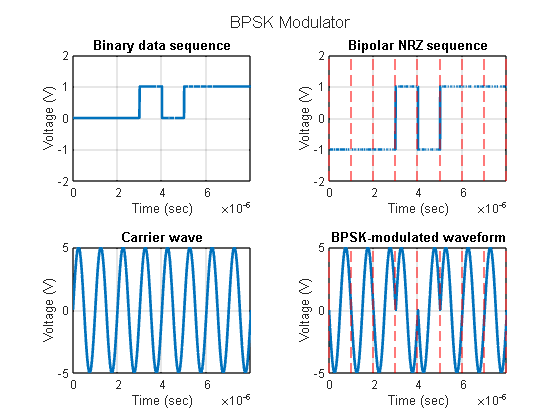

complex_envelope =   -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i


noise_complex_envelope = 1.0e+02 *

   2.1353 + 0.7154i  -0.7161 - 1.2484i   0.9684 - 0.6964i  -2.3065 - 1.2746i   4.2090 - 2.2936i   2.0935 - 2.0320i   1.7706 - 0.4693i  -1.9685 - 3.7988i


recovered_bits =      0     1     0     1     0     0     0     1


number = 3

ratio = 0.3750

clf
figure(1)
tiledlayout(2, 2)
sgtitle("BPSK Modulator")

nexttile % Binary data sequence
plot(T, binwave, LineWidth=2)
title("Binary data sequence")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
ylim([-2 2])
grid on

nexttile % Bipolar NRZ sequence
plot(T, NRZ, LineWidth=2)
title("Bipolar NRZ sequence")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
ylim([-2 2])
for i = 0 : length(bin), xline(i/fc, LineStyle='--', Color='red'); end
grid on

nexttile % Carrier wave
plot(T, carrier, LineWidth=2)
title("Carrier wave")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
grid on

nexttile % BPSK-modulated waveform
plot(T, BPSK, LineWidth=2)
title("BPSK-modulated waveform")
xlabel("Time (sec)")
ylabel("Voltage (V)")
xlim([0 max(T)])
for i = 0 : length(bin), xline(i/fc, LineStyle='--', Color='red'); end
grid on